config.l_x = 0.05;
config.l_y = 0.555;
config.l_z = 0.225;
config.l_d = 0.210;

ctrl_effectiveness = ...
[-(config.l_z + config.l_y)*5      ,config.l_z  ,0           ,0,0,-0.1667; ...
 (config.l_z + config.l_y)*5      ,config.l_z  ,0           ,0,0,-0.1667;...
 sqrt(config.l_z^2 + config.l_y^2),           0,0           ,0,0,0;...
                                 0,config.l_z*2,config.l_y*2,0,0,0;...
 sqrt(config.l_z^2 + config.l_y^2),           0,0           ,0,0,0;...
                                 0,config.l_z*2,config.l_y*2,0,0,0];


ub = [35*9.8;
      35*9.8;
      0;
      deg2rad(22);
      deg2rad(27);
      deg2rad(22)];
lb = [2.3*9.8;
      2.3*9.8;
      deg2rad(-27);
      deg2rad(-22);
      deg2rad(0);
      deg2rad(-22)];
N = 6;
result = zeros(N^6,6);
result2 = zeros(N^6,6);
result3 = zeros(N^6,6);
singular_val = zeros(N^6,6);
count = 1;
% F_r = linspace(lb(1),ub(1),N);
% F_l = linspace(lb(2),ub(2),N);
% theta_rr = linspace(lb(3),ub(3),N);
% theta_rp = linspace(lb(4),ub(4),N);
% theta_lr = linspace(lb(5),ub(5),N);
% theta_lp = linspace(lb(6),ub(6),N);
for F_r = linspace(lb(1),ub(1),N)
    for F_l = linspace(lb(2),ub(2),N)
        for theta_rr = linspace(lb(3),ub(3),N)
            for theta_rp = linspace(lb(4),ub(4),N)
                for theta_lr = linspace(lb(5),ub(5),N)
                    for theta_lp = linspace(lb(6),ub(6),N)
                        config.F_r = F_r;
                        config.F_l = F_l;
                        config.theta_rr = theta_rr;
                        config.theta_rp = theta_rp;
                        config.theta_lr = theta_lr;
                        config.theta_lp = theta_lp;

                        result(count,:) = getPreFT(config);
                        singular_val(count,:) = svd(getFTjacobe(config));
%                         result2(count,:) = ( (ctrl_effectiveness')*result(count,:)' - [F_r F_l theta_rr theta_rp theta_lr theta_lp]')';
                        test = (ctrl_effectiveness)*result(count,:)';
                        config.F_r =      max( min(test(1),ub(1)) , lb(1) );
                        config.F_l =      max( min(test(2),ub(2)) , lb(2) );
                        config.theta_rr = max( min(test(3),ub(3)) , lb(3) );
                        config.theta_rp = max( min(test(4),ub(4)) , lb(4) );
                        config.theta_lr = max( min(test(5),ub(5)) , lb(5) );
                        config.theta_lp = max( min(test(6),ub(6)) , lb(6) );
                        result2(count,:) = getPreFT(config);
                        result3(count,:) = getPreFT(config) - result(count,:);
                        count = count + 1;
                    end
                end
            end
        end
    end
end

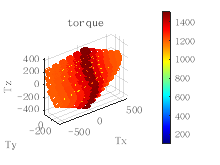

color_torque = (max(singular_val(:,1:3),[],2)./min(singular_val(:,1:3),[],2));
color_force = (max(singular_val(:,4:6),[],2) - min(singular_val(:,4:6),[],2));

color_torque_delta = max(singular_val(:,1:3),[],2); %%静态分配和雅可比之间的差值
color_force_delta = max(singular_val(:,4:6),[],2);

figure;
scatter3(result(:,1),result(:,2),result(:,3),20,color_torque_delta);
% hold on;
% scatter3(result2(:,1),result2(:,2),result2(:,3));
% hold off;
colormap(gca,"jet");colorbar;
xlabel('Tx');
ylabel('Ty');
zlabel('Tz');
title('torque');
axis equal

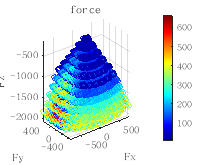

figure;
scatter3(result(:,4),result(:,5),result(:,6),20,color_force_delta);
% hold on;
% scatter3(result2(:,4),result2(:,5),result2(:,6));
% hold off;
colormap(gca,"jet");colorbar;
xlabel('Fx');
ylabel('Fy');
zlabel('Fz');
title('force');
axis equal

function result = getPreFT(config)
l_x = config.l_x;
l_y = config.l_y;
l_z = config.l_z;
l_d = config.l_d;

F_r = config.F_r;
F_l = config.F_l;
theta_rr = config.theta_rr;% 3
theta_rp = config.theta_rp;% 4
theta_lr = config.theta_lr;% 5
theta_lp = config.theta_lp;% 6
F = [- 3.0*F_l*sin(theta_lp) - 3.0*F_r*sin(theta_rp);
       3.0*F_l*cos(theta_lp)*sin(theta_lr) + 3.0*F_r*cos(theta_rp)*sin(theta_rr);
     - 3.0*F_l*cos(theta_lp)*cos(theta_lr) - 3.0*F_r*cos(theta_rp)*cos(theta_rr)];

T = [3.0*F_l*l_y*cos(theta_lp)*cos(theta_lr) - 3.0*F_r*l_y*cos(theta_rp)*cos(theta_rr) + 3.0*F_l*l_z*cos(theta_lp)*sin(theta_lr) + 3.0*F_r*l_z*cos(theta_rp)*sin(theta_rr);
     3.0*F_l*l_z*sin(theta_lp) + 3.0*F_r*l_z*sin(theta_rp) + F_l*cos(theta_lp)*cos(theta_lr)*(l_d - 1.0*l_x) + F_r*cos(theta_rp)*cos(theta_rr)*(l_d - 1.0*l_x) - 1.0*F_l*cos(theta_lp)*cos(theta_lr)*(l_d + l_x) - 1.0*F_r*cos(theta_rp)*cos(theta_rr)*(l_d + l_x) - 1.0*F_l*l_x*cos(theta_lp)*cos(theta_lr) - 1.0*F_r*l_x*cos(theta_rp)*cos(theta_rr);
     3.0*F_r*l_y*sin(theta_rp) - 3.0*F_l*l_y*sin(theta_lp) + F_l*cos(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) + F_r*cos(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x) - 1.0*F_l*cos(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*F_r*cos(theta_rp)*sin(theta_rr)*(l_d + l_x) - 1.0*F_l*l_x*cos(theta_lp)*sin(theta_lr) - 1.0*F_r*l_x*cos(theta_rp)*sin(theta_rr)];
Fx = F(1);
Fy = F(2);
Fz = F(3);
Tx = T(1);
Ty = T(2);
Tz = T(3);
result = [Tx,Ty,Tz,Fx,Fy,Fz];
end
function jacobe = getFTjacobe(config)
l_x = config.l_x;
l_y = config.l_y;
l_z = config.l_z;
l_d = config.l_d;

F_r = config.F_r;
F_l = config.F_l;
theta_rr = config.theta_rr;% 3
theta_rp = config.theta_rp;% 4
theta_lr = config.theta_lr;% 5
theta_lp = config.theta_lp;% 6

% f_jacob = [-3.0*sin(theta_rp), -3.0*sin(theta_lp), 0, -3.0*F_r*cos(theta_rp), 0, -3.0*F_l*cos(theta_lp);
%              3.0*cos(theta_rp)*sin(theta_rr), 3.0*cos(theta_lp)*sin(theta_lr), 3.0*F_r*cos(theta_rp)*cos(theta_rr), -3.0*F_r*sin(theta_rp)*sin(theta_rr), 3.0*F_l*cos(theta_lp)*cos(theta_lr), -3.0*F_l*sin(theta_lp)*sin(theta_lr);
%             -3.0*cos(theta_rp)*cos(theta_rr), -3.0*cos(theta_lp)*cos(theta_lr), 3.0*F_r*cos(theta_rp)*sin(theta_rr), 3.0*F_r*cos(theta_rr)*sin(theta_rp), 3.0*F_l*cos(theta_lp)*sin(theta_lr), 3.0*F_l*cos(theta_lr)*sin(theta_lp)];
f_jacob = [-3.0*sin(theta_rp), -3.0*sin(theta_lp), 0, -3.0*F_r*cos(theta_rp), 0, -3.0*F_l*cos(theta_lp); 3.0*cos(theta_rp)*sin(theta_rr), 3.0*cos(theta_lp)*sin(theta_lr), 3.0*F_r*cos(theta_rr), -3.0*F_r*sin(theta_rp)*sin(theta_rr), 3.0*F_l*cos(theta_lr), -3.0*F_l*sin(theta_lp)*sin(theta_lr); -3.0*cos(theta_rp)*cos(theta_rr), -3.0*cos(theta_lp)*cos(theta_lr), 3.0*F_r*sin(theta_rr), 3.0*F_r*cos(theta_rr)*sin(theta_rp), 3.0*F_l*sin(theta_lr), 3.0*F_l*cos(theta_lr)*sin(theta_lp)];
% T_jacob = [3.0*l_z*cos(theta_rp)*sin(theta_rr) - 3.0*l_y*cos(theta_rp)*cos(theta_rr), 3.0*l_y*cos(theta_lp)*cos(theta_lr) + 3.0*l_z*cos(theta_lp)*sin(theta_lr), 3.0*F_r*l_z*cos(theta_rp)*cos(theta_rr) + 3.0*F_r*l_y*cos(theta_rp)*sin(theta_rr), 3.0*F_r*l_y*cos(theta_rr)*sin(theta_rp) - 3.0*F_r*l_z*sin(theta_rp)*sin(theta_rr), 3.0*F_l*l_z*cos(theta_lp)*cos(theta_lr) - 3.0*F_l*l_y*cos(theta_lp)*sin(theta_lr), - 3.0*F_l*l_y*cos(theta_lr)*sin(theta_lp) - 3.0*F_l*l_z*sin(theta_lp)*sin(theta_lr);
%             3.0*l_z*sin(theta_rp) - 3.0*l_x*cos(theta_rp)*cos(theta_rr),   3.0*l_z*sin(theta_lp) - 3.0*l_x*cos(theta_lp)*cos(theta_lr),   3.0*F_r*l_x*cos(theta_rp)*sin(theta_rr), 3.0*F_r*l_z*cos(theta_rp) + 3.0*F_r*l_x*cos(theta_rr)*sin(theta_rp),   3.0*F_l*l_x*cos(theta_lp)*sin(theta_lr), 3.0*F_l*l_z*cos(theta_lp) + 3.0*F_l*l_x*cos(theta_lr)*sin(theta_lp);
%             3.0*l_y*sin(theta_rp) - 3.0*l_x*cos(theta_rp)*sin(theta_rr), - 3.0*l_x*cos(theta_lp)*sin(theta_lr) - 3.0*l_y*sin(theta_lp), - 3.0*F_r*l_x*cos(theta_rp)*cos(theta_rr), 3.0*F_r*l_y*cos(theta_rp) + 3.0*F_r*l_x*sin(theta_rp)*sin(theta_rr), - 3.0*F_l*l_x*cos(theta_lp)*cos(theta_lr), 3.0*F_l*l_x*sin(theta_lp)*sin(theta_lr) - 3.0*F_l*l_y*cos(theta_lp)];
T_jacob = [3.0*l_z*cos(theta_rp)*sin(theta_rr) - 3.0*l_y*cos(theta_rp)*cos(theta_rr), 3.0*l_y*cos(theta_lp)*cos(theta_lr) + 3.0*l_z*cos(theta_lp)*sin(theta_lr), 3.0*F_r*l_z*cos(theta_rr) + 3.0*F_r*l_y*sin(theta_rr), 3.0*F_r*l_y*cos(theta_rr)*sin(theta_rp) - 3.0*F_r*l_z*sin(theta_rp)*sin(theta_rr), 3.0*F_l*l_z*cos(theta_lr) - 3.0*F_l*l_y*sin(theta_lr), - 3.0*F_l*l_y*cos(theta_lr)*sin(theta_lp) - 3.0*F_l*l_z*sin(theta_lp)*sin(theta_lr); 3.0*l_z*sin(theta_rp) - 1.0*cos(theta_rp)*cos(theta_rr)*(l_d + l_x) - 1.0*l_x*cos(theta_rp)*cos(theta_rr) + cos(theta_rp)*cos(theta_rr)*(l_d - 1.0*l_x), 3.0*l_z*sin(theta_lp) - 1.0*cos(theta_lp)*cos(theta_lr)*(l_d + l_x) - 1.0*l_x*cos(theta_lp)*cos(theta_lr) + cos(theta_lp)*cos(theta_lr)*(l_d - 1.0*l_x), F_r*sin(theta_rr)*(l_d + l_x) - 1.0*F_r*sin(theta_rr)*(l_d - 1.0*l_x) + F_r*l_x*sin(theta_rr), 3.0*F_r*l_z*cos(theta_rp) - 1.0*F_r*cos(theta_rr)*sin(theta_rp)*(l_d - 1.0*l_x) + F_r*cos(theta_rr)*sin(theta_rp)*(l_d + l_x) + F_r*l_x*cos(theta_rr)*sin(theta_rp), F_l*sin(theta_lr)*(l_d + l_x) - 1.0*F_l*sin(theta_lr)*(l_d - 1.0*l_x) + F_l*l_x*sin(theta_lr), 3.0*F_l*l_z*cos(theta_lp) - 1.0*F_l*cos(theta_lr)*sin(theta_lp)*(l_d - 1.0*l_x) + F_l*cos(theta_lr)*sin(theta_lp)*(l_d + l_x) + F_l*l_x*cos(theta_lr)*sin(theta_lp); 3.0*l_y*sin(theta_rp) - 1.0*cos(theta_rp)*sin(theta_rr)*(l_d + l_x) - 1.0*l_x*cos(theta_rp)*sin(theta_rr) + cos(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x), cos(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) - 1.0*cos(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*l_x*cos(theta_lp)*sin(theta_lr) - 3.0*l_y*sin(theta_lp), F_r*cos(theta_rr)*(l_d - 1.0*l_x) - 1.0*F_r*cos(theta_rr)*(l_d + l_x) - 1.0*F_r*l_x*cos(theta_rr), 3.0*F_r*l_y*cos(theta_rp) - 1.0*F_r*sin(theta_rp)*sin(theta_rr)*(l_d - 1.0*l_x) + F_r*sin(theta_rp)*sin(theta_rr)*(l_d + l_x) + F_r*l_x*sin(theta_rp)*sin(theta_rr), F_l*cos(theta_lr)*(l_d - 1.0*l_x) - 1.0*F_l*cos(theta_lr)*(l_d + l_x) - 1.0*F_l*l_x*cos(theta_lr), F_l*sin(theta_lp)*sin(theta_lr)*(l_d + l_x) - 1.0*F_l*sin(theta_lp)*sin(theta_lr)*(l_d - 1.0*l_x) - 3.0*F_l*l_y*cos(theta_lp) + F_l*l_x*sin(theta_lp)*sin(theta_lr)];
jacobe = [T_jacob;f_jacob];
end